-  Comparison the estimators between using the sampled  mean and that of the conditional expectation 

- Estimation 

1) the sampled mean

If you have a measured data  $z =\{z_1 , z_2 ,..., z_n \}$, which is random,for example measure  the number of n person's height.What is the best estimation of the height? One estimation is the sample average , i.e., 


$$\bar{m}_z  =  \frac{1}_{n} \sum_{i=1}^{n} z_i $$


Or if it is know the pdf of the height, luckly, the mean (or expectration) of the height is 


$$E[Z] = \int \ zf(z)dx$$


which it the best estimator without noise information

2) The estimated state is constant but  the measurement noise is characterized as a gaussian so that the measurement is modeled 

                                                    
$$z=\bar{x\;} +v\;\;\;,v~N\left(0,V\right)$$


Then the estimator of the state $\bar{x\;} \;$is the sampled estimator as

                                              
$$E\left\lbrack z\right\rbrack =E\left\lbrack \bar{x} +v\right\rbrack =\bar{x} +E\left\lbrack v\right\rbrack =\bar{x\;}$$


 3) The state is also random, i.e., 

                                            
$$z=\textrm{Hx}+v\;\;\;,x\;~\;N\left(\textrm{mx},M\right),\;v~N\left(0,V\right)$$


Then the best estimator of the state is the conditional expectation, which is called a Kalman filter. The algorithm is as following :            

                                   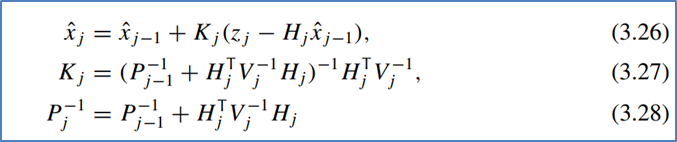

Here        

$z_j$: the measurement at time $j$

${\hat{x\;} }_j :$the conditional estimator of the state $x$ at time $j$

$\hat{K_j } :$ the gain(Kalman gain) at time $j$

${\hat{P\;} }_j \;$the conditional covaraince of the state $x$ and the estimator at time $j$

with initial condition 

${\hat{x\;} }_0 =\textrm{mX}$, $P_0 =M$

- Comparison between the estimators using the sampled and the Kalman

Here is the simulation comparison

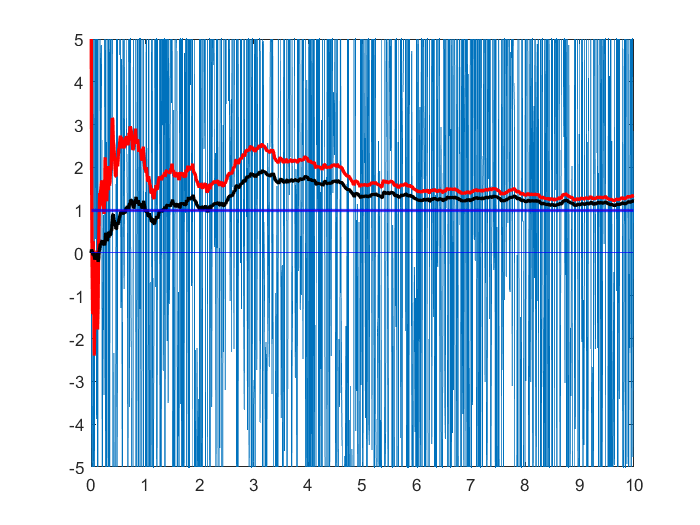

clear all;clf 
rng('default')
n = 1000;    % number of sampling 
t = linspace(0,10,n);
mX = 1; M =1;        
mV = 0;
% V =1;       
V = 100 ;  % large 

x = mX + sqrt(M)*randn(n,1);   % x ~ N(mX, M)
v = mV + sqrt(V)*randn(n,1);   % v ~ N(mV, V)
z = x + v;

plot(t,z); hold on
axis([0 10 -5 5])
yline(0, 'b');
yline(mX,'r');
% compariosn the estimators between the sample mean and the conditional
% expectation. Remeber the conditional expectation is implemented through
% Kalman filter.

sampleZ(1) = z(1);      % initialize the sample mean
condEst(1) = 0; P=1;   % initialize the conditional mean
% condEst(1) = mX; P=M;   % initialize the conditional mean
for k = 1:n-1
    P= inv(inv(P) + inv(V));
    K = inv(inv(P) + inv(V))*inv(V);   
    
    z(k) = x(k) + v(k); 
    sampleZ(k+1) =k/(k+1)*sampleZ(k) + 1/(k+1)*z(k+1);
    condEst(k+1) = condEst(k) + K*(z(k)-condEst(k));
    
end
plot(t, sampleZ,'linewidth',2, 'color','r');
plot(t,condEst(1:n), 'linewidth',2,'color','k') 
yline(mX,'b', 'linewidth',2);

Here the sampled and Kalman is similar to each other. Why the Kalman?

1) Analysis with respect to initial points 

   In the kalman filter, the initial points should be defined, whereas the sampled case is not. It is difficult to find the mean and variance at the initial state. However 

even if the initial point are approximated, the Kalman result is similiar , in the code you may check. Hence even if the initial points is uncertain, Kalman is OK. 

2) Noise variance effect

Now the noise variance is difficult to estimate, however,we may simulate to analyize its effects. If the nosie varaince is large than the that of the state, 

assume the nosie variance = 100, then the sampled estimation is worse than the conditional case. 

3) Here the model is non-drift case, next, we may consider the drift case. 